# Rad229 - Lecture 8:  Spin-Echo Sequences

## lec8_01.m:  Simple Spin-Echo Formation

This example simply simulates the steps to a spin-echo at these 5 points from Lecture 8, slide 7:

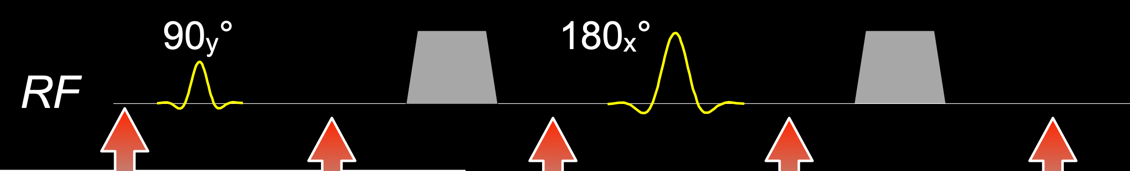

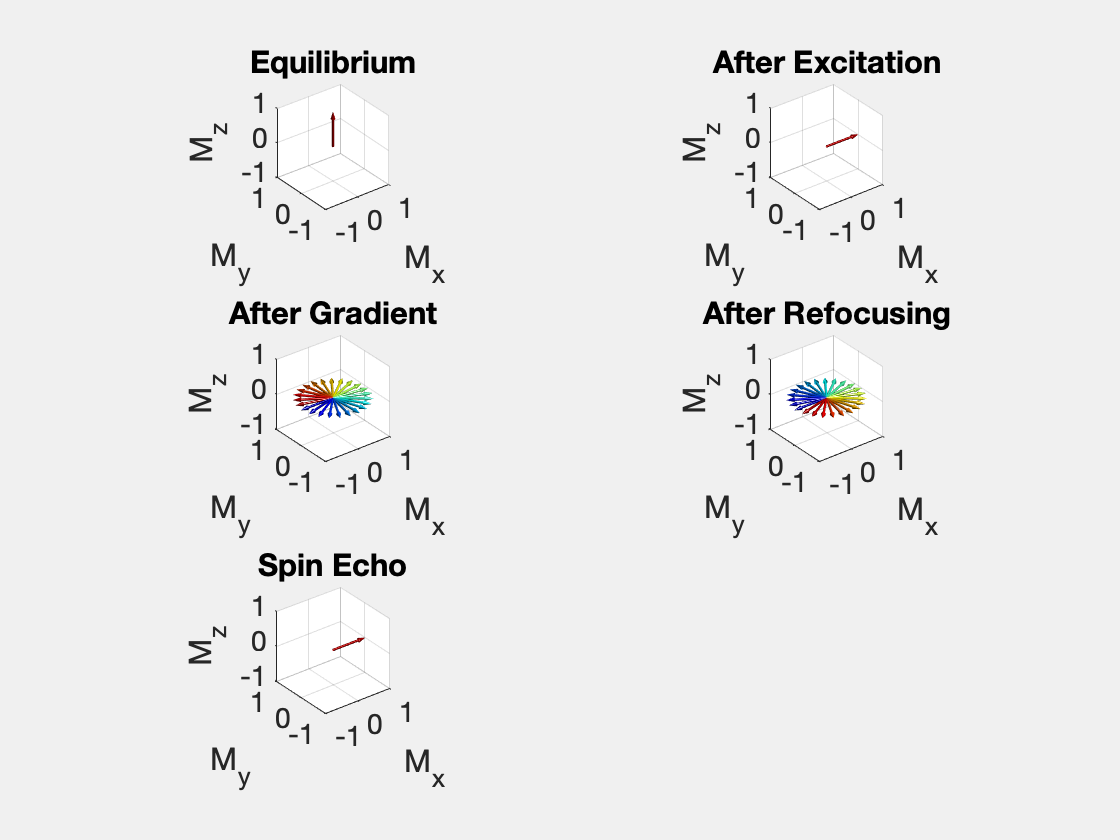


% Lecture 8, Example 01
%
% Simulate a simple 90-gradient-RF-gradient to a spin echo, using EPG

refoc_angle = pi;

figure(1); clf;

subplot(3,2,1);
Q = epg_m0();   % Start at equilibrium
epg_showstate(Q); title('Equilibrium'); 

subplot(3,2,2);
Q = epg_rf(Q,pi/2,pi/2);      % Flip 90 about y
epg_showstate(Q); title('After Excitation'); 

subplot(3,2,3);
Q = epg_grad(Q);
epg_showstate(Q); title('After Gradient'); 

subplot(3,2,4);
Q = epg_rf(Q,refoc_angle,0);   % Flip 180 about x
epg_showstate(Q); title('After Refocusing'); 

subplot(3,2,5);
Q = epg_grad(Q);
epg_showstate(Q); title('Spin Echo'); 

lec8_02.m:  Calculate steady-state spin-echo signal

This assumes a 90-180, with crusher gradients, then another gradient at the end of TR.  We generally assume that TR>>T2, but the gradient at the end might help a bit if this is not true.

% Lecture 8, Example 02
%
% Calculation of basic signal in a spin-echo sequence using EPG

T1=2;   % sec
T2=0.1  % sec

T2 = 0.1000

TR=1;   % sec
TE=0.05;% sec
N = 2   % cycles (Nth cycle signal saved)

N = 2


Q = epg_m0();   % Start at equilibrium

for n=1:N       % Repeat twice, to get to steady-state

  Q = epg_rf(Q,pi/2,pi/2);      % Flip 90 about y
  Q = epg_grelax(Q,T1,T2,TE/2,0,0,1);   % Gradient to TE/2
  Q = epg_rf(Q,pi,0);   % Flip 180 about x
  Q = epg_grelax(Q,T1,T2,TE/2,0,0,1);   % Gradient to TE

  Qecho = Q;    % Save spin-echo signal

  Q = epg_grelax(Q,T1,T2,TR-TE,0,0,1);  % TE to TR.
                                        % Set last 1 to 0 to not dephase

end;

tt = sprintf('Spin-Echo signal on TR %d is %g',N,Qecho(1)); disp(tt);

Spin-Echo signal on TR 2 is 0.229397


Exercise:

1) Try changing TR, TE, and N to see the effect

## lec8_03.m:  Spin-echo with non-180° refocusing

Repeats exampe 1, but for non-180° refocusing.  Also displays the EPG states sequentially over time (may run better outside Matlab live).

% Lecture 8, Example 03
%
% Simulate a simple 90-gradient-RF-gradient to a spin echo, using EPG
% Same as example 1, but showing all EPG states.

refoc_angle = 120/180*pi;

figure(1); clf;

Q = epg_m0();   % Start at equilibrium
epg_show(Q); title('Equilibrium'); disp('press enter'); pause;

press enter



Q = epg_rf(Q,pi/2,pi/2);      % Flip 90 about y
epg_show(Q); title('After Excitation'); disp('press enter'); pause;

press enter



Q = epg_grad(Q);
epg_show(Q); title('After Gradient'); disp('press enter'); pause;

press enter



Q = epg_rf(Q,refoc_angle,0);   % Refocus about x
epg_show(Q); title('After Refocusing'); disp('press enter'); pause;

press enter


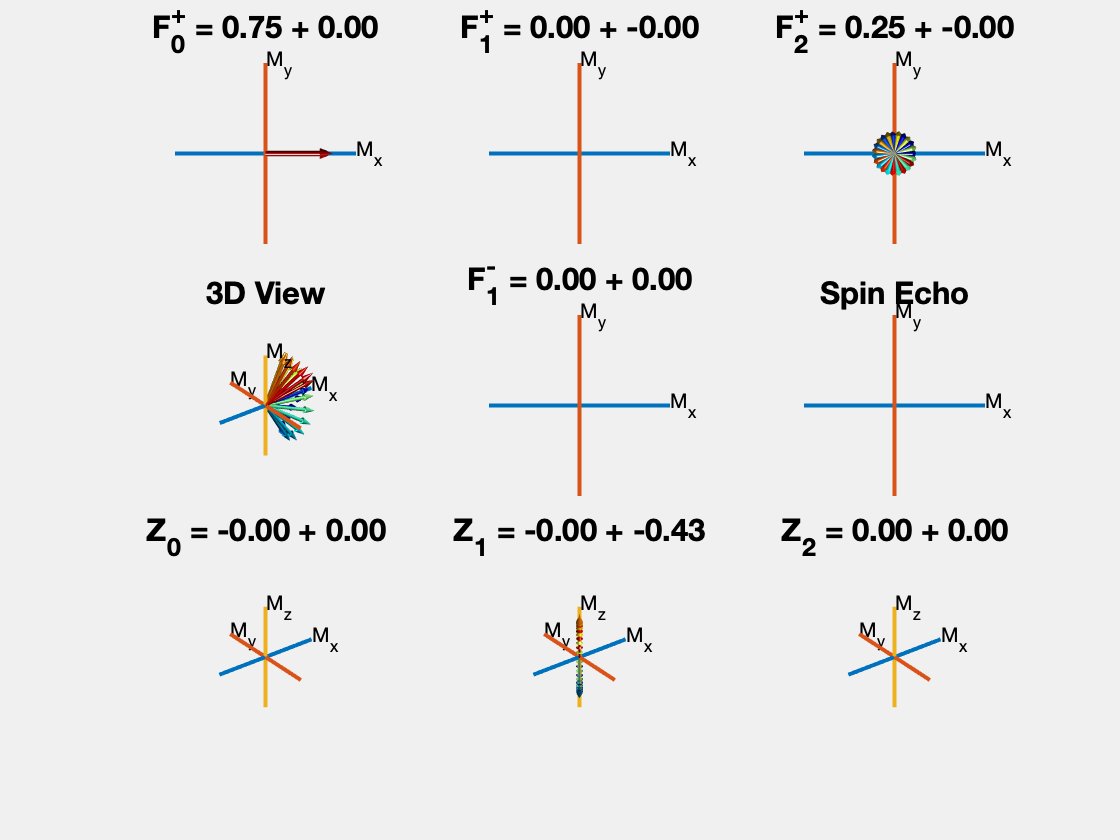

press enter



Q = epg_grad(Q);
epg_show(Q); title('Spin Echo'); disp('press enter'); pause;

Exercise:

1) Try changing the refocusing angle

## lec8_04.m:  Signal vs Refocusing Angle (epg_cpmg.m)

Calculate signal vs flip angle for different cases with epg_cpmg.m

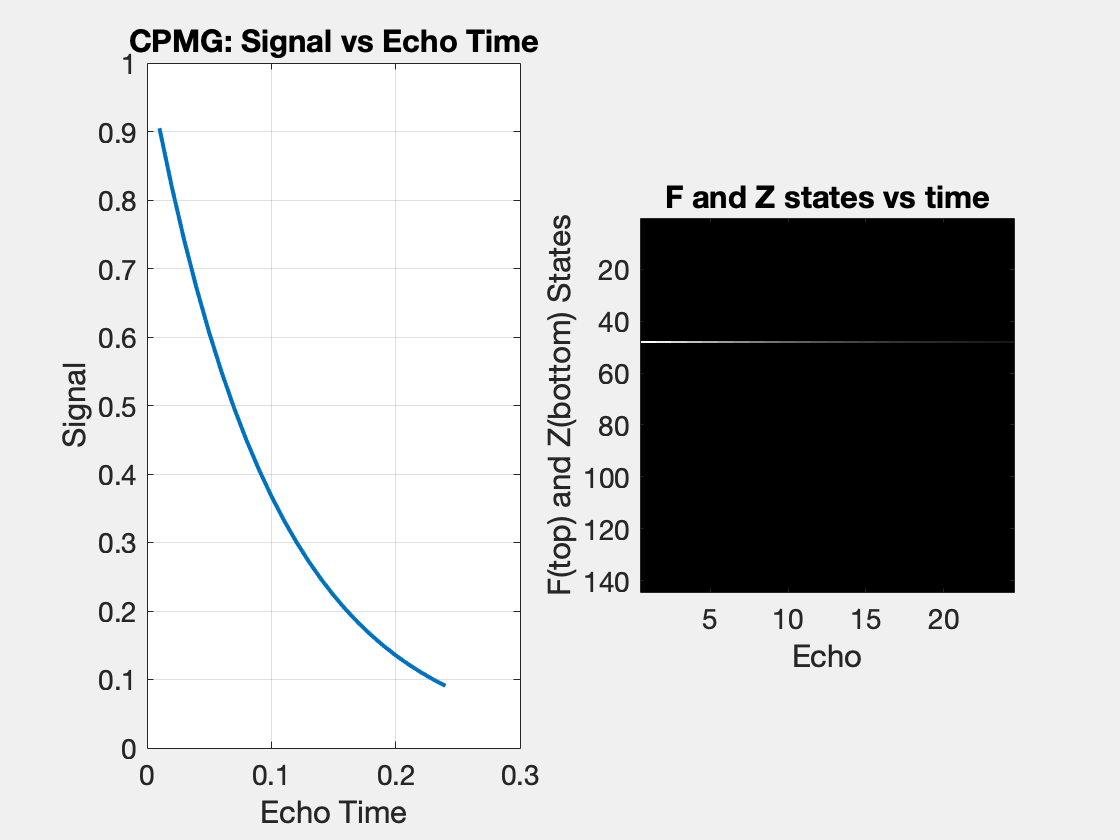

stabilization added


flipangle =     1.7453    0.3491    0.3491    0.3491    0.3491    0.3491    0.3491    0.3491    0.3491    0.3491    0.3491    0.3491    0.3491    0.3491    0.3491    0.3491    0.3491    0.3491    0.3491    0.3491    0.3491    0.3491    0.3491    0.3491


stabilization added


flipangle =     1.9199    0.6981    0.6981    0.6981    0.6981    0.6981    0.6981    0.6981    0.6981    0.6981    0.6981    0.6981    0.6981    0.6981    0.6981    0.6981    0.6981    0.6981    0.6981    0.6981    0.6981    0.6981    0.6981    0.6981


stabilization added


flipangle =     2.0944    1.0472    1.0472    1.0472    1.0472    1.0472    1.0472    1.0472    1.0472    1.0472    1.0472    1.0472    1.0472    1.0472    1.0472    1.0472    1.0472    1.0472    1.0472    1.0472    1.0472    1.0472    1.0472    1.0472


stabilization added


flipangle =     2.2689    1.3963    1.3963    1.3963    1.3963    1.3963    1.3963    1.3963    1.3963    1.3963    1.3963    1.3963    1.3963    1.3963    1.3963    1.3963    1.3963    1.3963    1.3963    1.3963    1.3963    1.3963    1.3963    1.3963


stabilization added


flipangle =     2.4435    1.7453    1.7453    1.7453    1.7453    1.7453    1.7453    1.7453    1.7453    1.7453    1.7453    1.7453    1.7453    1.7453    1.7453    1.7453    1.7453    1.7453    1.7453    1.7453    1.7453    1.7453    1.7453    1.7453


stabilization added


flipangle =     2.6180    2.0944    2.0944    2.0944    2.0944    2.0944    2.0944    2.0944    2.0944    2.0944    2.0944    2.0944    2.0944    2.0944    2.0944    2.0944    2.0944    2.0944    2.0944    2.0944    2.0944    2.0944    2.0944    2.0944


stabilization added


flipangle =     2.7925    2.4435    2.4435    2.4435    2.4435    2.4435    2.4435    2.4435    2.4435    2.4435    2.4435    2.4435    2.4435    2.4435    2.4435    2.4435    2.4435    2.4435    2.4435    2.4435    2.4435    2.4435    2.4435    2.4435


stabilization added


flipangle =     2.9671    2.7925    2.7925    2.7925    2.7925    2.7925    2.7925    2.7925    2.7925    2.7925    2.7925    2.7925    2.7925    2.7925    2.7925    2.7925    2.7925    2.7925    2.7925    2.7925    2.7925    2.7925    2.7925    2.7925


flipangle =     3.1416    3.1416    3.1416    3.1416    3.1416    3.1416    3.1416    3.1416    3.1416    3.1416    3.1416    3.1416    3.1416    3.1416    3.1416    3.1416    3.1416    3.1416    3.1416    3.1416    3.1416    3.1416    3.1416    3.1416


% Lecture 8, Example 04
%
% First demonstration of epg_cpmg.m for constant refocusing pulses with stabilization and CPMG

flips = 20*[1:9];       % Repeat for different refocusing angles
etl = 24;
set(0,'defaultAxesFontSize',14);        % Default font sizes
set(0, 'DefaultLineLineWidth', 2);      % Default line width
fliplist = {};

figure(1); clf
for k=1:length(flips)
  s = epg_cpmg(flips(k)*pi/180,etl);    % Will plot each time, just keep last.
  sigs(:,k) = s(:);
  fliplist = {fliplist{:}, sprintf('%d',flips(k))};
end;

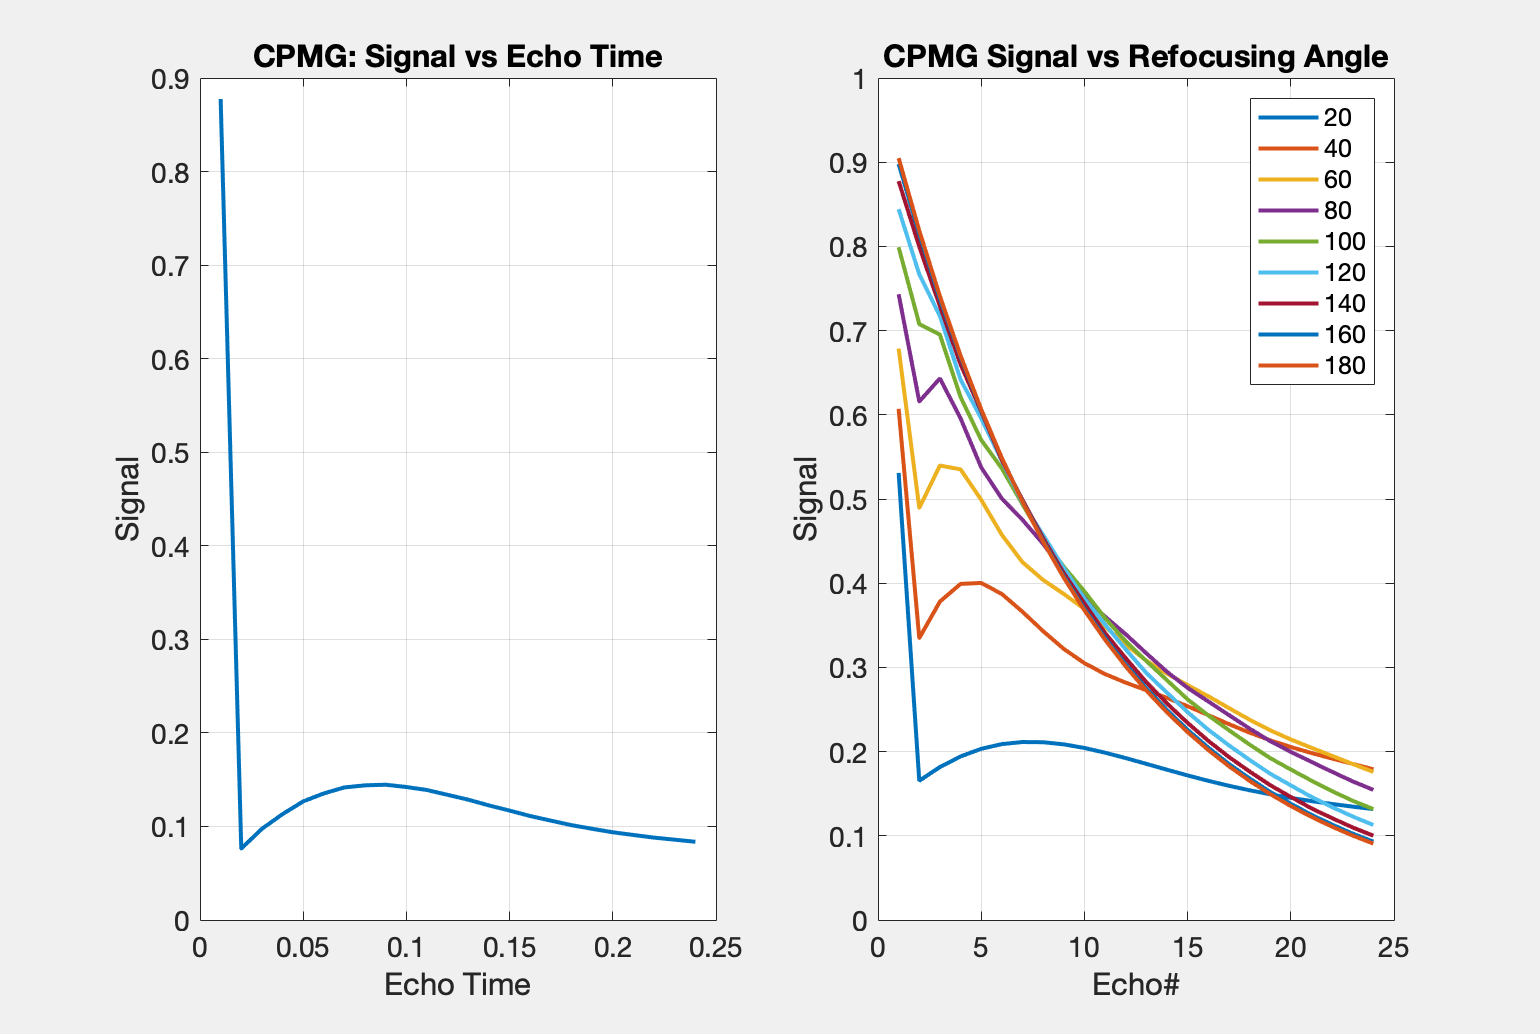


figure(2);
plot([1:etl],abs(sigs));
lplot('Echo#','Signal','CPMG Signal vs Refocusing Angle');
legend(fliplist);

lec8_05.m    Stabilize the signal for 60-degree refocusing

Notice that the single-flip-angle doesn't work so well.  Try changing the first flip angles in this arry to make the signal transition more smooth.

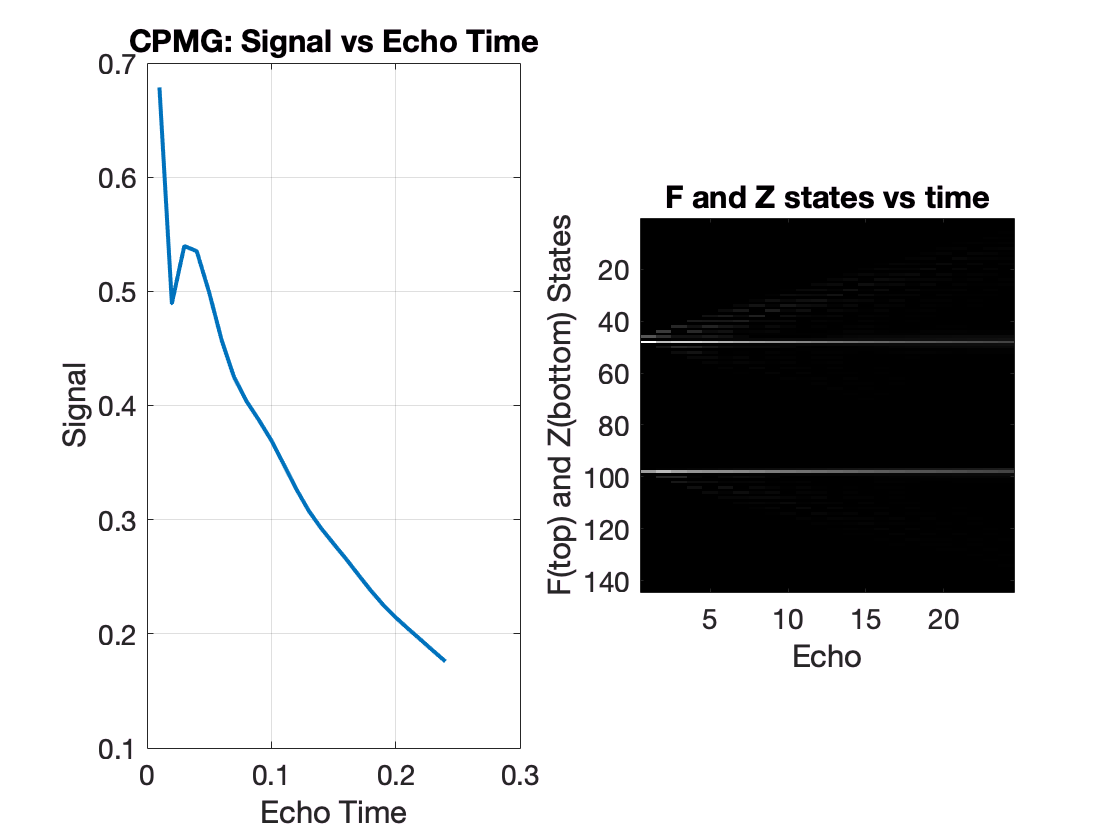

% Lecture 8, Example 05
%
% Try to stabilize the 60-degree refocusing flip angle signal

clf;
flips = pi/180*[120 60*ones(1,23)];
set(0,'defaultAxesFontSize',14);        % Default font sizes
set(0, 'DefaultLineLineWidth', 2);      % Default line width

s = epg_cpmg(flips);  